# Fitting a Linear SSM of the Lorenz-63 System

## Finding the best fitting parameters

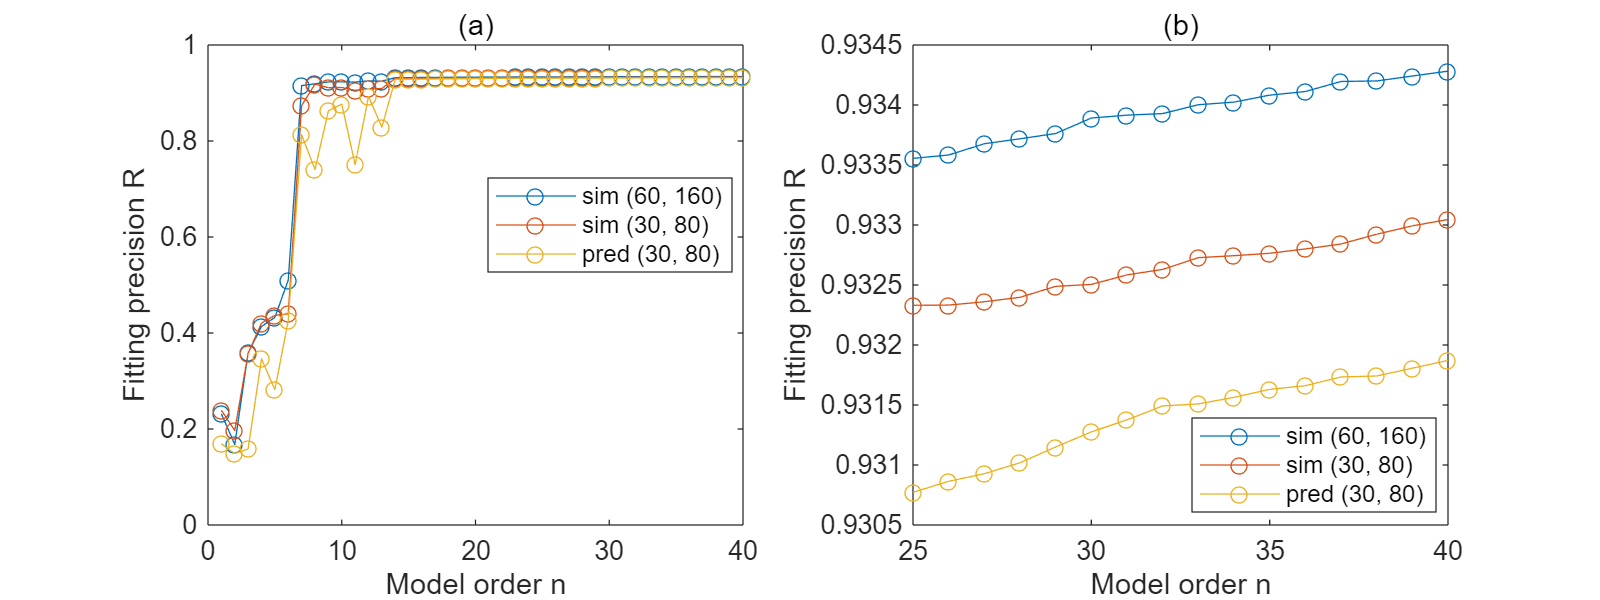

% % Vary the parameters of n4opt to get the best parameter settings
n4opt1 = n4sidOptions('N4Weight','CVA', "Focus","simulation", "N4Horizon",[60,0,160]);
n4opt2 = n4sidOptions('N4Weight','CVA', "Focus","simulation", "N4Horizon",[30,0,80]);
n4opt3 = n4sidOptions('N4Weight','CVA', "Focus","prediction", "N4Horizon",[30,0,80]);
n4optset = {n4opt1,n4opt2,n4opt3};
nxrange = 1:40;

sysset = cell(length(n4optset), length(nxrange));
for k = 2:length(n4optset)
    for l = 1:length(nxrange)
        sys = n4sid(dat, nxrange(l), n4optset{k});
        sysset{k,l} = sys;
        fprintf("Fitting of SSM with n4opt%d and n=%d finished\n", k, nxrange(l));
    end
end

u = transpose(get(dat).InputData{1}); % Input
y = transpose(get(dat).OutputData{1}); % Actual output
w = [1/6;1/6;2/3];

Rset = NaN(length(n4optset), length(nxrange));
for k = 1:length(n4optset)
    for l = 1:length(nxrange)
        sys = sysset{k,l};
        [~,y_tier] = ssm(sys,u); % Simulated output
        aux = simerr(y,y_tier,w);
        if imag(aux) ~= 0
            aux = 0;
        end
        Rset(k,l) = aux;
    end
end

% Visualization
figure
scnsize  = get(0,'ScreenSize'); 
len = 800;
wid = 300;
set(gcf,'Position', [scnsize(1,3)/2-len/2, scnsize(1,4)/2-wid/2,len, wid]);

% Broad overview
subplot(1,2,1);
plot(nxrange, Rset, "Marker","o")
legend("sim (60, 160)", "sim (30, 80)", "pred (30, 80)", 'Location', 'best')
xlabel("Model order n")
ylabel("Fitting precision R")
title("(a)")

% Close up
subplot(1,2,2);
close_range = 25:40;
plot(close_range, Rset(:,close_range), "Marker","o")
legend("sim (60, 160)", "sim (30, 80)", "pred (30, 80)", 'Location', 'best')
xlabel("Model order n")
ylabel("Fitting precision R")
title("(b)")

exportgraphics(gcf, [filedir '\fitting_precision.pdf'], 'ContentType', 'vector', 'BackgroundColor', 'none');

% % System identification with the best parameter settings

% Notice: Due to version differences of MATLAB System Identification Toolbox,
% parameter estimation may fail or take an impractically long time for
% certain cases. If that happens, users can indentify the subsystem for
% x,y and subsystem for z independently since the linear SSM was proved to
% be decoupled in our article

n4opt = n4sidOptions('N4Weight','CVA', "Focus","simulation", "N4Horizon",[60,0,160]);
nx = 32;
sys_Lorenz = n4sid(dat_mer, nx, n4opt);

## Validation of the fitted linear SSM

sys = sys_Lorenz; % The parameter matrices of sys_Lorenz is also stored in linear_ssm_of_Lornez63.mat, which is sufficient for analyzing the properties of the linear SSM in our study

y = transpose(get(dat).OutputData{1}); % Actual time domain response
Y = fft_single(y); % Actual frequency domain response

u = transpose(get(dat).InputData{1}); % Input data
[Y_tier,y_tier] = ssm(sys,u); % Modelled frequency/ time domain response

% Compute the fitting precision
w = [1/6,1/6,2/3]';
R = fitting_precision(y,y_tier,w);
fprintf("Fitting precision is: %d\n", R);

Fitting precision is: 9.338459e-01


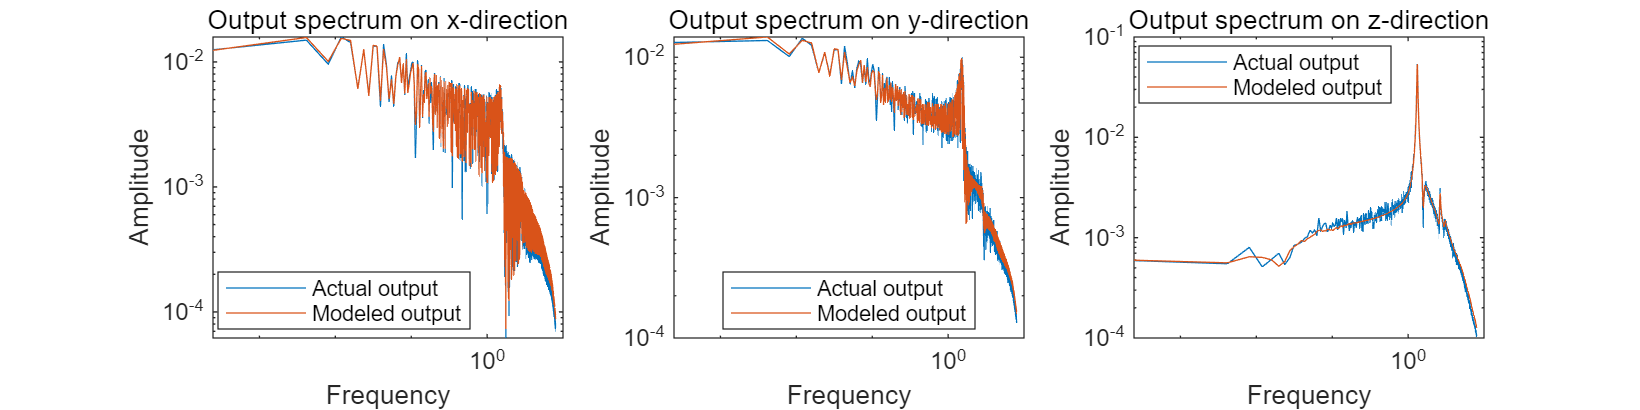


% Visualization of the comparison between the actual and modelled output
figure;
scnsize  = get(0,'ScreenSize'); 
len = 1200;
wid = 300;
set(gcf,'Position', [scnsize(1,3)/2-len/2, scnsize(1,4)/2-wid/2,len, wid]);

subplot(1,3,1)
loglog(Fs/N1*fre,abs(Y(1,fre+1)), Fs/N1*fre,abs(Y_tier(1,fre+1)))
legend("Actual output","Modeled output", 'Location','best')
xlabel("Frequency")
ylabel("Amplitude")
xlim([0 10])
title("Output spectrum on x-direction")

subplot(1,3,2)
loglog(Fs/N1*fre,abs(Y(2,fre+1)), Fs/N1*fre,abs(Y_tier(2,fre+1)))
legend("Actual output","Modeled output", 'Location','best')
xlabel("Frequency")
ylabel("Amplitude")
xlim([0 10])
title("Output spectrum on y-direction")

subplot(1,3,3)
loglog(Fs/N1*fre,abs(Y(3,fre+1)), Fs/N1*fre,abs(Y_tier(3,fre+1)))
legend("Actual output","Modeled output", 'Location','best')
xlabel("Frequency")
ylabel("Amplitude")
xlim([0 10])
title("Output spectrum on z-direction")

exportgraphics(gcf, [filedir '\comparison.pdf'], 'ContentType', 'vector', 'BackgroundColor', 'none');

## Decoupling of the linear SSM

% % Transform matrix A into a real Jordan carnonical form
sys = sys_Lorenz;

[A, B, C, x0, K] = ssm2ABC(sys);
nx = length(A);

% Eigenvalues and eigenvectors
[V,D] = eig(A);
Lambda = diag(D);

% Sort the eigenvalues, seperate complex and real ones
ind_real = find(imag(Lambda)==0);
ind_imag = setdiff(1:length(Lambda),ind_real);
[~,sort_ind_real] = sort(Lambda(ind_real),"descend");
[~,sort_ind_imag] = sort(real(Lambda(ind_imag)),"descend");
sort_ind = zeros(1,length(Lambda));
sort_ind(1:length(ind_imag)) = ind_imag(sort_ind_imag);
sort_ind(length(ind_imag)+1:end) = ind_real(sort_ind_real);
D = diag(Lambda(sort_ind));
V = V(:,sort_ind);

% Real Jordan carnonical form
n = size(A,1);
J = zeros(n);
P = zeros(n);

used = false(n,1);
i = 1;
p_col = 1;
while i <= n
    if used(i)
        i = i + 1;
        continue;
    end
    lambda = D(i,i);
    if isreal(lambda)
        % 1x1 part corresponding to real eigenvalue
        J(p_col,p_col) = lambda;
        P(:,p_col) = V(:,i);
        used(i) = true;
        i = i + 1;
        p_col = p_col + 1;
    else
        % 2x2 part corresponding to conjucated complex eigenvalue
        a = real(lambda);
        b = imag(lambda);
        J(p_col:p_col+1, p_col:p_col+1) = [a b; -b a];
        v = V(:,i);
        P(:,p_col) = real(v);
        P(:,p_col+1) = imag(v);
        used(i) = true;
        used(i+1) = true;
        i = i + 2;
        p_col = p_col + 2;
    end
end

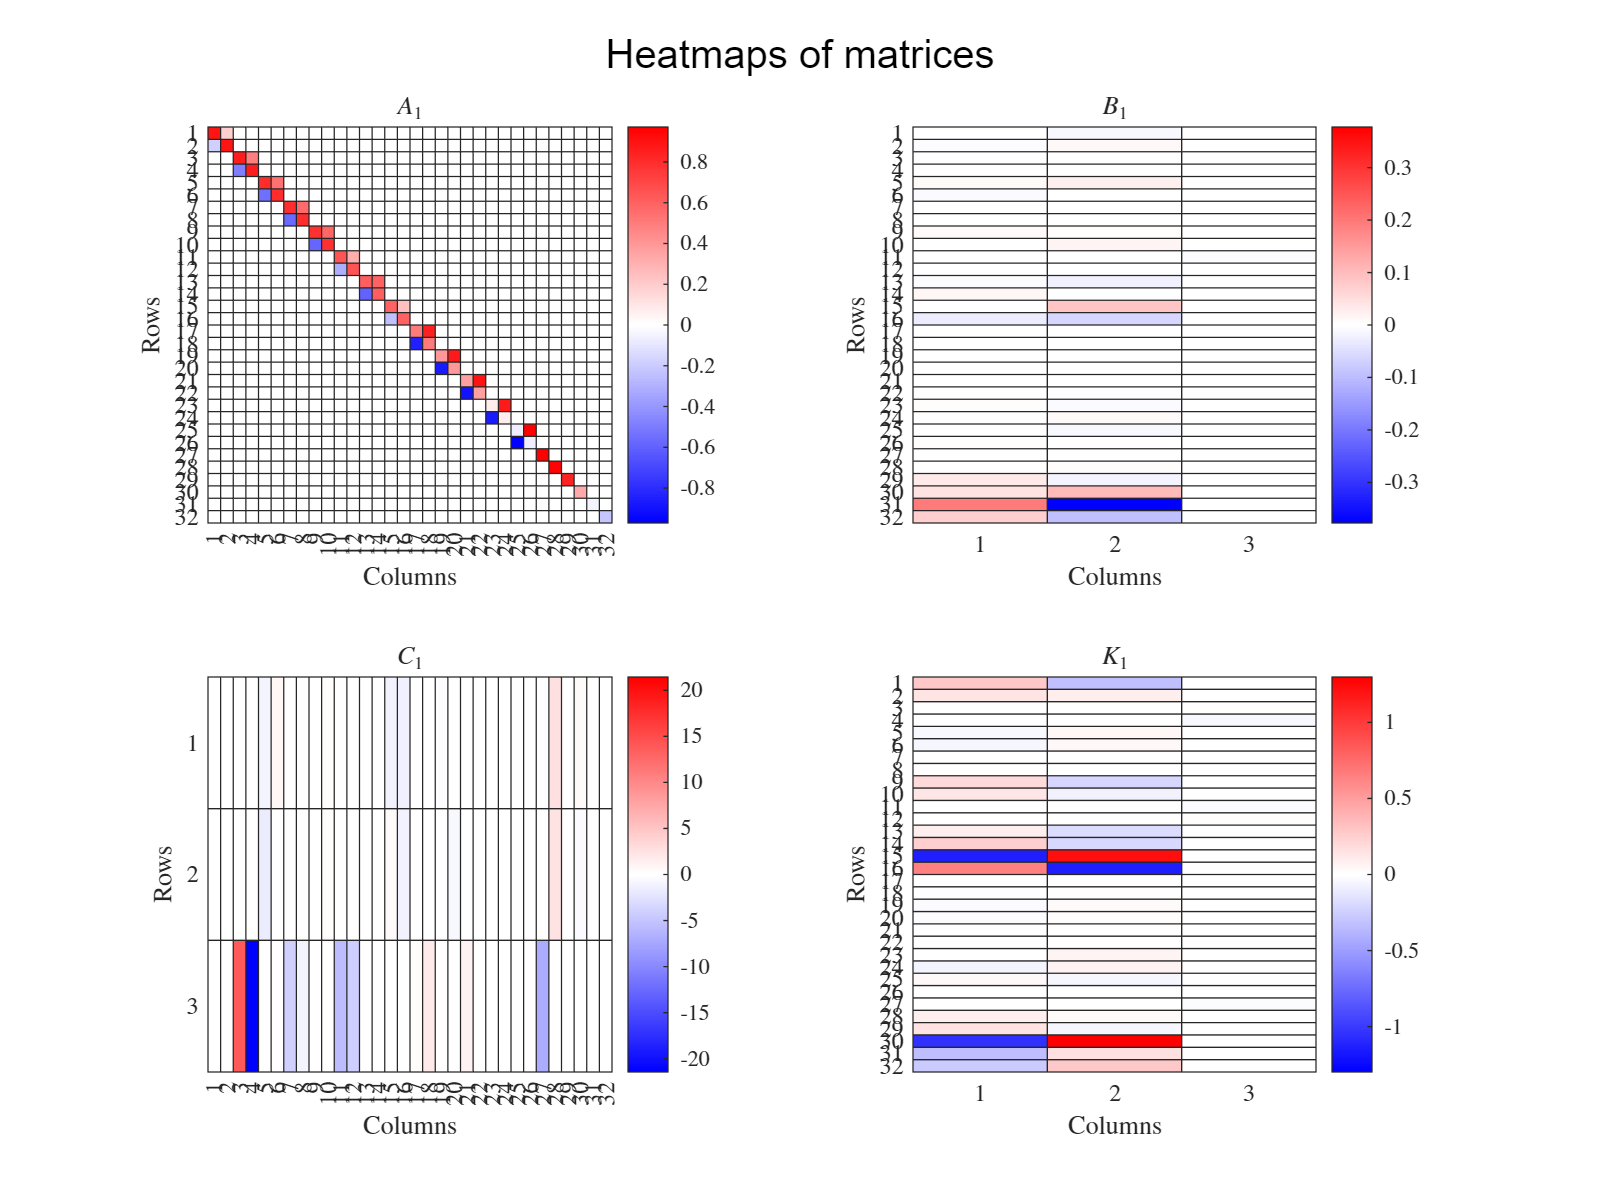

% % Produce the heatmaps of the transformed matrices
scnsize  = get(0,'ScreenSize'); 
len = 800;
wid = 600;
set(gcf,'Position', [scnsize(1,3)/2-len/2, scnsize(1,4)/2-wid/2,len, wid]);
sgtitle("Heatmaps of matrices") % General Title

subplot(2,2,1);
mat_heatmap(A1,'$A_1$');

subplot(2,2,2);
B1 = P^(-1)*B;
mat_heatmap(B1,'$B_1$');

subplot(2,2,3);
C1 = C*P;
mat_heatmap(C1,'$C_1$');

subplot(2,2,4);
K1 = P^(-1)*K;
mat_heatmap(K1,'$K_1$');

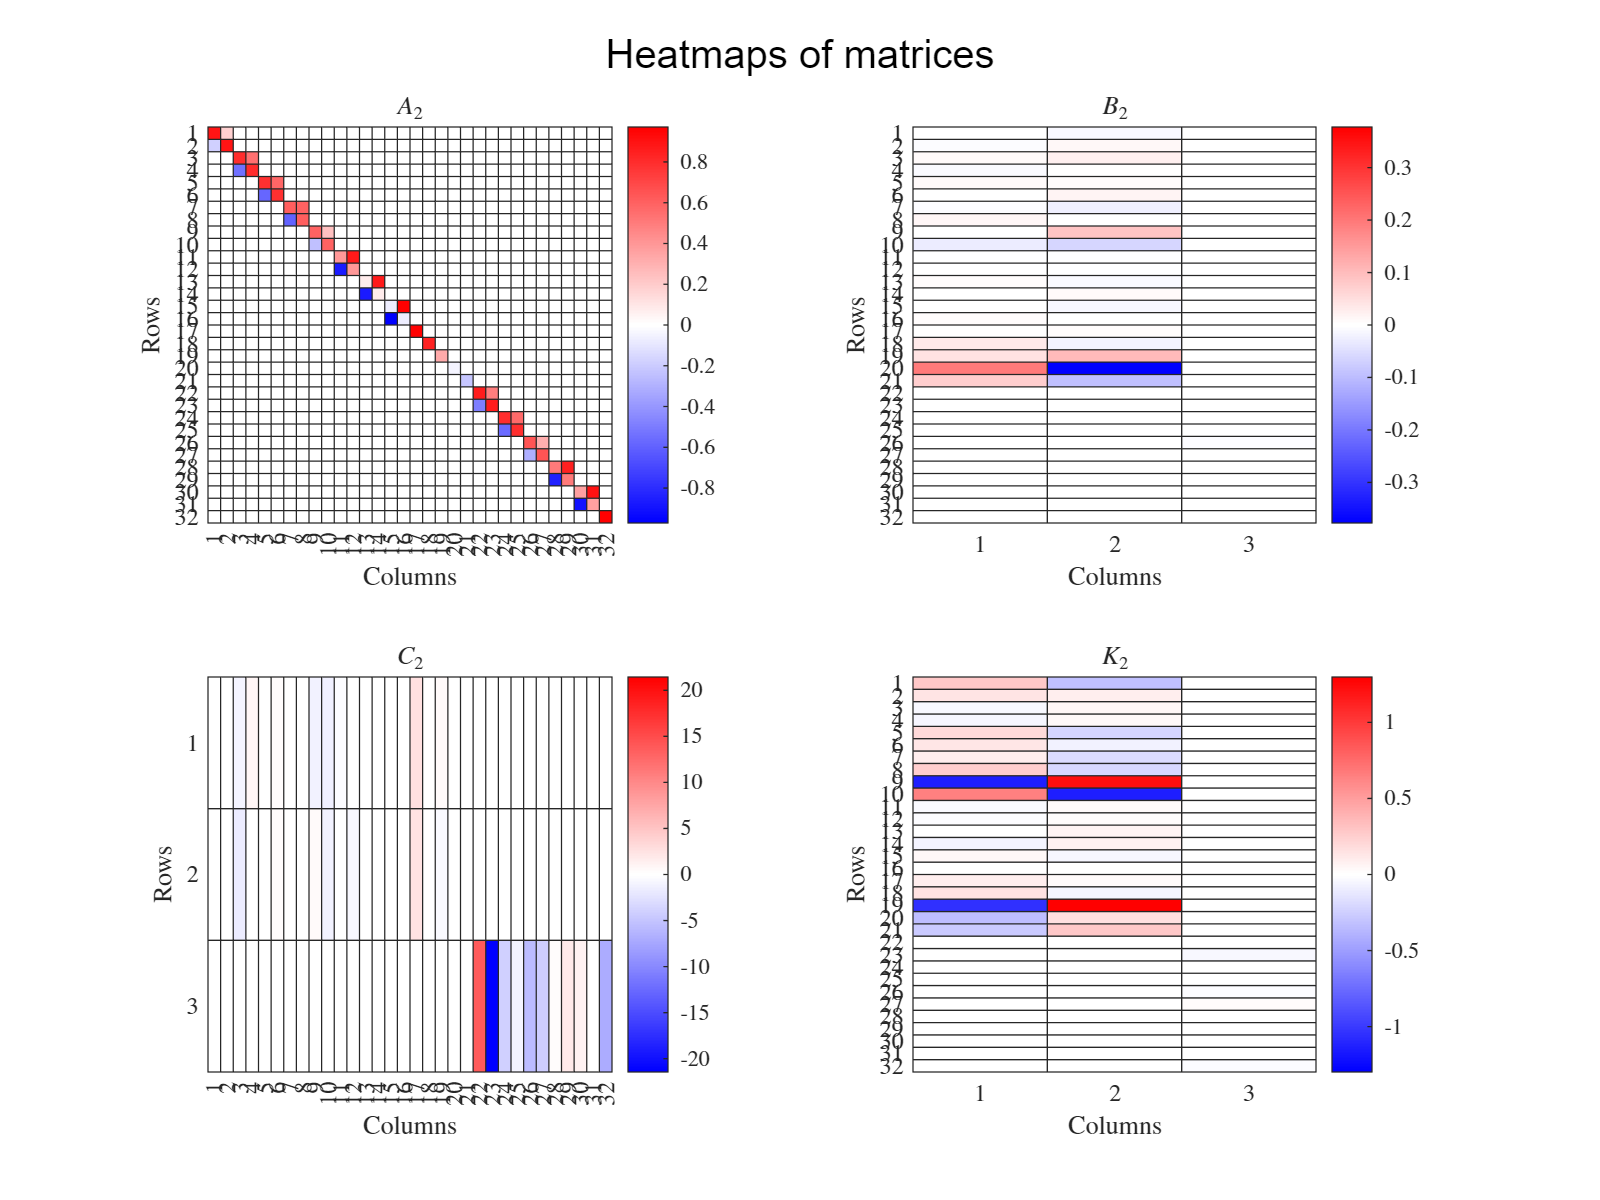

% % Decoupling of the linear SSM
dominant_ind3 = find(abs(C1(3,:)) > 1e-9); % Indices of the nonzero elements of the 3rd row of matrix C1

% Rearrange the latent variables for better illustration
sort_ind = [setdiff(1:nx,dominant_ind3), dominant_ind3];
Q = zeros(nx);
for i = 1:nx
    Q(sort_ind(i),i) = 1;
end

% Visualization
scnsize  = get(0,'ScreenSize'); 
len = 800;
wid = 600;
set(gcf,'Position', [scnsize(1,3)/2-len/2, scnsize(1,4)/2-wid/2,len, wid]);
sgtitle("Heatmaps of matrices") % General Title

subplot(2,2,1);
A2 = Q^(-1)*A1*Q;
mat_heatmap(A2,'$A_2$');
subplot(2,2,2);
B2 = Q^(-1)*B1;
mat_heatmap(B2,'$B_2$');
subplot(2,2,3);
C2 = C1*Q;
mat_heatmap(C2,'$C_2$');
subplot(2,2,4);
K2 = Q^(-1)*K1;
mat_heatmap(K2,'$K_2$');

% % The original linear SSM can be decoupled into two subsystems, one for
% x, y and one for z
num_dominant = length(dominant_ind3);
w0 = Q^(-1)*P^(-1)*x0; % w = Q^(-1)*P^(-1)*x

A_xy = A2(1:nx-num_dominant,1:nx-num_dominant);
B_xy = B2(1:nx-num_dominant,1:2);
C_xy = C2(1:2,1:nx-num_dominant);
K_xy = K2(1:nx-num_dominant,1:2);
sys_diag_xy = {A_xy,B_xy,C_xy,w0(1:nx-num_dominant),K_xy}; % Subsystem for x,y with order n_xy
n_xy = length(A_xy);

A_z = A2(nx-num_dominant+1:end,nx-num_dominant+1:end);
B_z = B2(nx-num_dominant+1:end,3);
C_z = C2(3,nx-num_dominant+1:end);
K_z = K2(nx-num_dominant+1:end,3);
sys_diag_z = {A_z,B_z,C_z,w0(nx-num_dominant+1:end),K_z}; % Subsystem for z with order n_z
n_z = length(A_z);